# Step Counter

clc, clear;
%Need to put it in the same timetable: same timebase
% Think about what data the classification needs
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks

folder = "/MATLAB Drive/MobileSensorData";
fullMatFileName = fullfile(folder, "Step100.mat");
if~exist(fullMatFileName, "file")
    uiwait("%s does not exist", fullMatFileName);
else
    s=load(fullMatFileName);
    
end

dataAccel = s.Acceleration;
dataOrien = s.Orientation;
clear s;
[dataAccel, dataOrien] = DataClean(dataAccel, dataOrien);


features = retime(dataAccel, "regular","mean","TimeStep", seconds(2.5));
features = renamevars(features,["X","Y","Z"],["Xaccel","Yaccel","Zaccel"]);

features2 = retime(dataOrien, "regular","mean","TimeStep", seconds(2.5));
features2 = renamevars(features2,["X","Y","Z"],["Xorien","Yorien","Zorien"]);

Classification = categorical(repmat("Walking",height(features),1));
featureData = [features, features2(:,1:end)];
featureData = addvars(featureData,Classification)

featureData = 31×7 timetable
           Timestamp            Xaccel    Yaccel     Zaccel     Xorien     Yorien    Zorien     Classification
    ________________________    ______    _______    _______    _______    ______    _______    ______________

    27-Mar-2023 08:42:05.000     4.081     -7.342    0.67064    -36.741     48.33    -67.734       Walking    
    27-Mar-2023 08:42:07.500    2.5573    -9.3751     1.0709      23.19    67.577    -51.588       Walking    
    27-Mar-2023 08:42:10.000    2.5696    -10.387      1.227    -47.051    69.435    -65.737       Walking    
    27-Mar-2023 08:42:12.500    2.9875    -9.6394    0.46818      4.456    

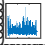


% Seconds = datevec(dataAccel.Timestamp);
% NumSec = Seconds(:,6);
% Start = round(NumSec(1));
% End = round(NumSec(end));
% Duration = End-Start;
% Xaxis = 1:1:Duration;

plot(dataAccel.Timestamp, dataAccel.X);
hold on
plot(dataAccel.Timestamp, dataAccel.Y);
hold on
plot(dataAccel.Timestamp, dataAccel.Z);
hold off
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

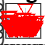

% xticklabels(Xaxis)





X = dataAccel.X;
Y = dataAccel.Y;
Z = dataAccel.Z;
mag = sqrt(sum(X.^2 + Y.^2 + Z.^2, 2));

plot(dataAccel.Timestamp, mag)
% xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


magNoG = mag - mean(mag);

plot(dataAccel.Timestamp,magNoG);
% xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


minPeakHeight = std(magNoG);

[pks,locs] = findpeaks(magNoG,'MINPEAKHEIGHT',minPeakHeight);

numSteps = numel(pks)

numSteps = 103

hold on;
plot(dataAccel.Timestamp(locs), pks, 'r', 'Marker', 'v', 'LineStyle', 'none');
title('Counting Steps');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
hold off;

m.AccelerationSensorEnabled = 0;

clear m;